# Programmentwurf Simulationstechnik

Gruppe: Batuhan Aykut (6697882), Lars Annuth (1140146), Liza Thöne (9434335)

**Aufgabe 1:**

Ermitteln Sie den Verlauf für den Schwimmwinkel und die Giergeschwindigkeit für den Fall, dass Sie den Radlenkwinkel auf delta = 5° bei einer Geschwindigkeit von v = 18 m/s * springen lassen,

Verwenden Sie dafür folgende Parameter: m = 2000kg, J = 4000kgm², lv = 1.43m, lh = 1.4m, cv = 70000 N/rad , ch = 140000 N/rad

Berechnen Sie die Lösung mit Hilfe von Matlab. Stellen Sie die Ergebnisse grafisch dar, geben Sie die Winkel bzw. Winkelgeschwindigkeit in ° bzw. °/s an.

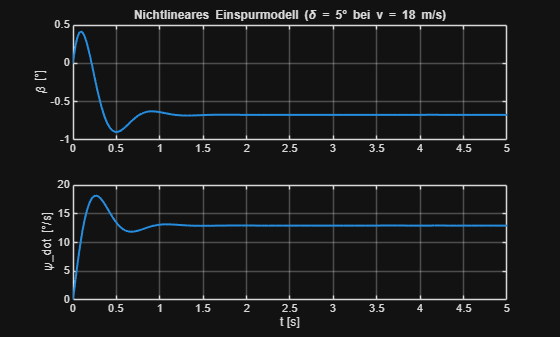

%% Parameter

m = 2000;       % Masse [kg]
J = 4000;       % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]
v = 18;         % Fahrzeuggeschwindigkeit [m/s]

delta = deg2rad(5);   % Lenkwinkel [rad]

%% Simulation mit ode45
tspan = [0 5];
x0 = [0; 0];   % Anfangswerte: [beta0; psi_dot0]

odefun = @(t,x) bicycleNL(t,x,m,J,lv,lh,cv,ch,v,delta);
[t,x] = ode45(odefun, tspan, x0);

beta    = x(:,1);      % [rad]
psi_dot = x(:,2);      % [rad/s]

%% Umrechnung in Grad
beta_deg    = rad2deg(beta);
psi_dot_deg = rad2deg(psi_dot);

%% Plot
figure
subplot(2,1,1)
plot(t, beta_deg, 'LineWidth', 1.5)
grid on
ylabel('\beta [°]')
title('Nichtlineares Einspurmodell (\delta = 5° bei v = 18 m/s)')

subplot(2,1,2)
plot(t, psi_dot_deg, 'LineWidth', 1.5)
grid on
ylabel('\psi\_dot [°/s]')
xlabel('t [s]')


%% Nichtlineare Modellgleichungen
function dx = bicycleNL(~, x, m, J, lv, lh, cv, ch, v, delta)

    beta    = x(1);   % Schwimmwinkel [rad]
    psi_dot = x(2);   % Giergeschwindigkeit [rad/s]

    % Schutz gegen cos(beta) → 0
    cb = cos(beta);
    if abs(cb) < 1e-6
        cb = sign(cb)*1e-6;
    end

    % Schräglaufwinkel
    alpha_v = delta - (lv*psi_dot)/(v*cb) + tan(beta);
    alpha_h =        (lh*psi_dot)/(v*cb) - tan(beta);

    % Nichtlineare Differentialgleichungen
    beta_dot = -psi_dot + (1/(m*v)) * (cv*alpha_v + ch*alpha_h);
    psi_ddot = (1/J) * (lv*cv*alpha_v*cos(delta) - lh*ch*alpha_h);

    dx = [beta_dot; psi_ddot];
end

**Beschreibung:**

In Aufgabe 1 wird das Fahrverhalten eines Pkw mithilfe eines nichtlinearen Einspurmodells untersucht. Ziel der Aufgabe ist es, den zeitlichen Verlauf des Schwimmwinkels β sowie der Giergeschwindigkeit ψ̇ zu bestimmen, wenn der Radlenkwinkel δ bei einer konstanten Fahrzeuggeschwindigkeit von v = 18 m/s sprunghaft auf 5° gesetzt wird.

Zunächst werden alle gegebenen Fahrzeugparameter definiert. Der Lenkwinkel wird von Grad in Radiant umgerechnet, da MATLAB intern mit Bogenmaß rechnet.

Als Zustandsgrößen werden der Schwimmwinkel β und die Giergeschwindigkeit ψ̇ gewählt. Das System wird nicht linearisiert, sondern es werden die vollständigen nichtlinearen Bewegungsgleichungen verwendet. Die Nichtlinearität entsteht durch die trigonometrischen Zusammenhänge in den Schräglaufwinkeln der Vorder- und Hinterachse. Diese ergeben sich zu


$$\alpha_v =\delta -\frac{l_v \cdot \Psi^{\prime } }{v\cdot \cos \left(\beta \right)}+\tan \left(\beta \right)$$



$$\alpha _h = \frac{l_h \cdot  \Psi'}{ v \cdot  \cos(\beta )} - \tan(\beta )
$$


Über die Schräglaufsteifigkeiten entstehen daraus die Seitenführungskräfte an Vorder- und Hinterachse. Diese Kräfte beeinflussen sowohl die seitliche Bewegung des Fahrzeugs als auch die Gierbewegung. Daraus ergeben sich zwei gekoppelte nichtlineare Differentialgleichungen für β und ψ̇.

Da es sich um ein nichtlineares System handelt, ist keine geschlossene analytische Lösung möglich. Stattdessen wird das Anfangswertproblem numerisch mit dem MATLAB-Solver `ode45` gelöst. Als Anfangsbedingungen werden β(0) = 0 und ψ̇(0) = 0 gewählt. Dies entspricht einem Fahrzeug, das sich zu Beginn ohne Seitenbewegung und ohne Gierbewegung geradeaus bewegt.

Der Lenkwinkel wird als Sprungfunktion modelliert, indem δ ab t = 0 konstant auf 5° gesetzt wird. Der ODE-Solver berechnet daraus den zeitlichen Verlauf der Zustände.

Die Ergebnisse werden anschließend von Radiant in Grad beziehungsweise Grad pro Sekunde umgerechnet und grafisch dargestellt. Der Verlauf zeigt, dass der Lenkwinkelsprung zunächst eine schnelle Zunahme der Giergeschwindigkeit verursacht. Das Fahrzeug beginnt sich um die Hochachse zu drehen. Gleichzeitig baut sich ein Schwimmwinkel auf, da die Bewegungsrichtung des Fahrzeugs von seiner Längsachse abweicht. Nach einer Übergangsphase stellt sich ein stationärer Zustand ein, der einer gleichförmigen Kurvenfahrt mit konstantem Lenkwinkel entspricht.

#### Aufgabe 2:

Bauen Sie die angegebenen Gleichungen in Simulink auf, führen Sie die gleiche Berechnung wie in Aufgabe 1 durch und stellen die Ergebnisse ebenfalls grafisch dar.

sim Aufgabe2_3.slx;

**Beschreibung:**

Das nichtlineare Einspurmodell wurde in Simulink mit zwei gekoppelten Differentialgleichungen mit den in Aufgabe 1 gegebenen Parametern implementiert.

Zuerst wurden die Gleichungen von den Schräglaufwinkeln dargestellt:


$$\alpha_v =\delta -\frac{l_v \cdot \Psi^{\prime } }{v\cdot \cos \left(\beta \right)}+\tan \left(\beta \right)$$



$$\alpha _h = \frac{l_h \cdot  \Psi'}{ v \cdot  \cos(\beta )} - \tan(\beta )
$$


und in die beiden Subsysteme "Schräglauf_vorne" und "Schräglauf_hinten" zusammengefasst.

Danach wurde die Gleichungen für die Schwimmwinkelgeschwindigkeit und die Gierbeschleunigung nachgebaut:


$$\beta^\prime = - \Psi^\prime + \frac{1}{mv}(c_v\alpha_v \frac{\cos \delta}{\cos \beta} + c_h\alpha_h \frac{1}{\cos \beta})$$



$$\Psi'' = (l_vc_v \alpha_v\cdot \cos(\delta ) - l_hc_h\alpha_h)\cdot \frac{1}{J}$$


und auch wieder in Subsysteme zusammengefasst. Für die Giergeschwindigkeit wurde die Beschleunigung integriert und ist dann in einem Scope sichtbar, ebenso wurde das für den Schwimmwinkel gemacht.

Durch den Vergleich mit der berechneten Lösung aus Aufgabe 1 konnte gezeigt werden, dass beide Implementierungen numerisch konsistente Ergebnisse liefern. Damit ist sichergestellt, dass das Modell korrekt in Simulink abgebildet wurde.

#### Aufgabe 3: 

Bestimmen Sie das** linearisierte Modell** für den Betriebspunkt δ = 0°, β = 0° und ψ = 0 °/s. Bauen Sie dieses lineare Modell ebenfalls in Simulink auf. Verwenden Sie die gleiche Datei und trennen das nichtlineare und lineare Modell, in dem Sie jeweils ein eigenes Subsystem anlegen.

Führen Sie eine Berechnung für die vorherigen Parameter jeweils für δ = 5° und δ = 20° durch. Vergleichen Sie die Ergebnisse des linearen und nichtlinearen Modells zum einen grafisch und zum anderen, indem Sie die maximale Abweichung zwischen linearem und nichtlinearen Modell berechnen und den Zahlenwert ausgeben.

Interpretieren Sie die Ergebnisse.

**Beschreibung:**

Die **Linearisierung** wurde mit Taylorentwicklung um den Betriebspunkt berechnet: 

Daraus ergeben sich für die trigonometrische Terme diese Nährungen:

$\cos(\beta) \approx 1$ ebenso bei $\cos(\delta) \approx 1$ 


$$\tan(\beta) \approx \beta$$


Weitere nicht lineare Term befinden sich nicht in den Gleichungen des Modells

Bei den Schräglaufwinkeln a_v und a_h ergibt sich damit als linearisierter Terme: 

$\alpha_v= \delta - \frac{l_v \Psi^{\prime\prime}}{v\cos \beta} + \tan \beta$ => $\alpha_v^{lin} = \delta - \frac{l_v \Psi^{\prime\prime}}{v} + \beta$

$\alpha _h = \frac{l_h \cdot  \Psi'}{ v \cdot  \cos \beta } - \tan \beta 
$ => $\alpha_h^{lin} =  \frac{l_h \Psi^{\prime\prime}}{v} - \beta$

Bei dem DGL ergeben sich nach der Linearisierung folgende Gleichungen: 

$\beta^\prime = - \Psi^\prime + \frac{1}{mv}(c_v\alpha_v \frac{\cos \delta}{\cos \beta} + c_h\alpha_h \frac{1}{\cos \beta})$ => $\beta^{\prime lin} = - \Psi^\prime + \frac{1}{mv}(c_v\alpha_v \frac{1}{1} + c_h\alpha_h \frac{1}{1}) = - \Psi^\prime + \frac{1}{mv}(c_v\alpha_v  + c_h\alpha_h) $

$\Psi'' = (l_vc_v \alpha_v\cdot \cos(\delta ) - l_hc_h\alpha_h)\cdot \frac{1}{J}$ => $\Psi^{\prime \prime lin} = (l_vc_v \alpha_v - l_hc_h\alpha_h)\cdot \frac{1}{J}$

Man erhält ein lineares zetinvariantes System. 

Dieses wurde in der Simulink-Datei als ein separates Subsystem implementiert.

sim Aufgabe2_3.slx;

**Vergleich: **

Die Simulation wurde für δ = 5° und δ = 20° durchgeführt.

Für  δ = 5°: Nicht-lineares Modell:

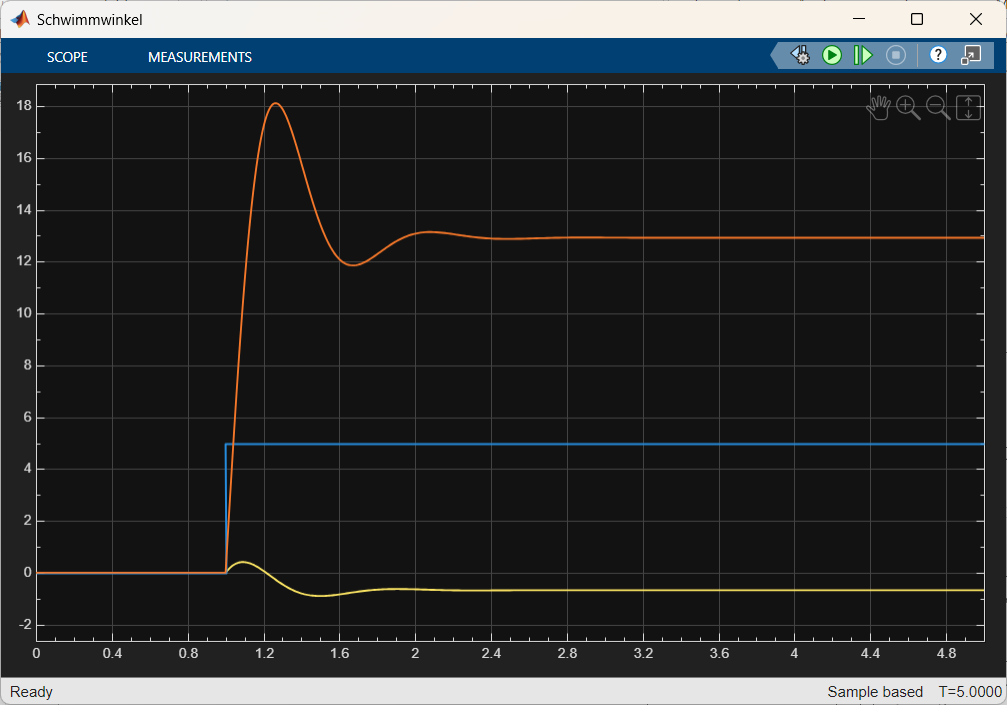

Linearisiertes Modell:

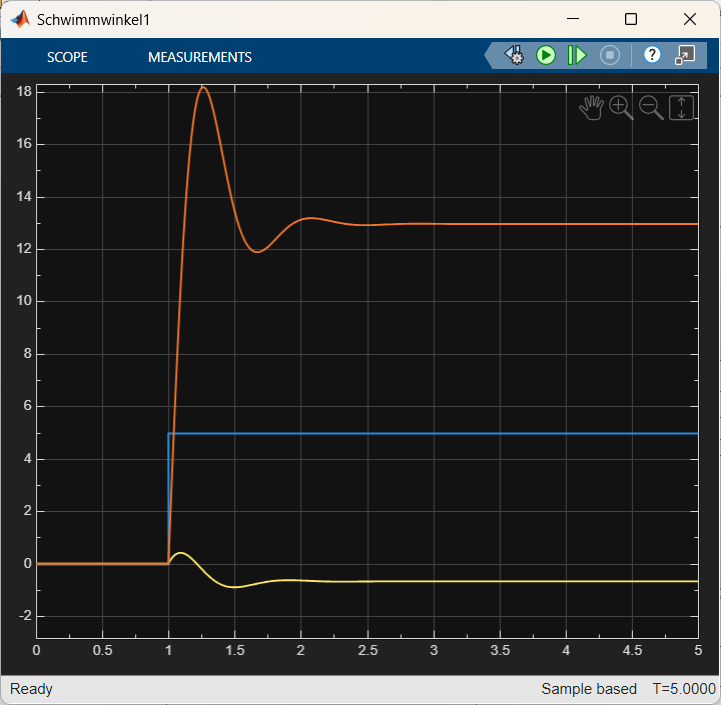

Abweichung: 

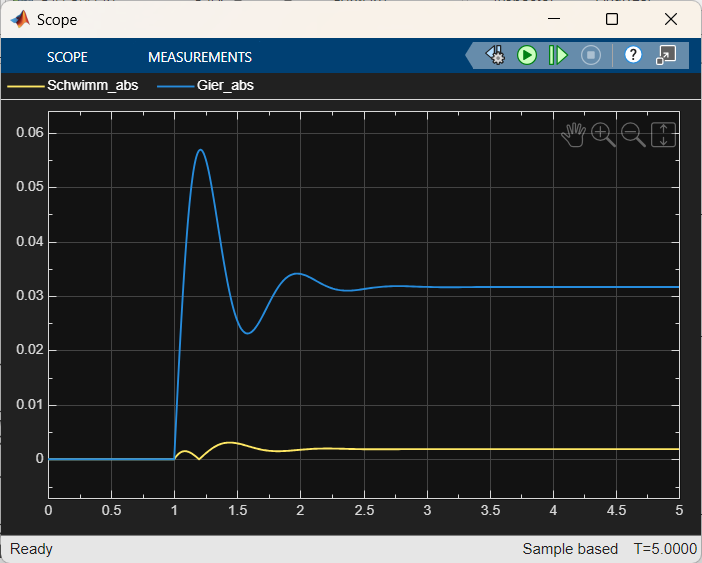

Für einen Lenkwinkelsprung von 5° stimmen die Verläufe im linearen und nichtlinearen Modell weitgehend überein. Die maximale Abweichung bleibt gering.

Dies ist erwartungsgemäß, da sich das System in der Nähe des Linearisierungspunktes befindet und die Kleinwinkelnäherungen gültig sind.

Nicht-Lineares Modell mit δ = 20°

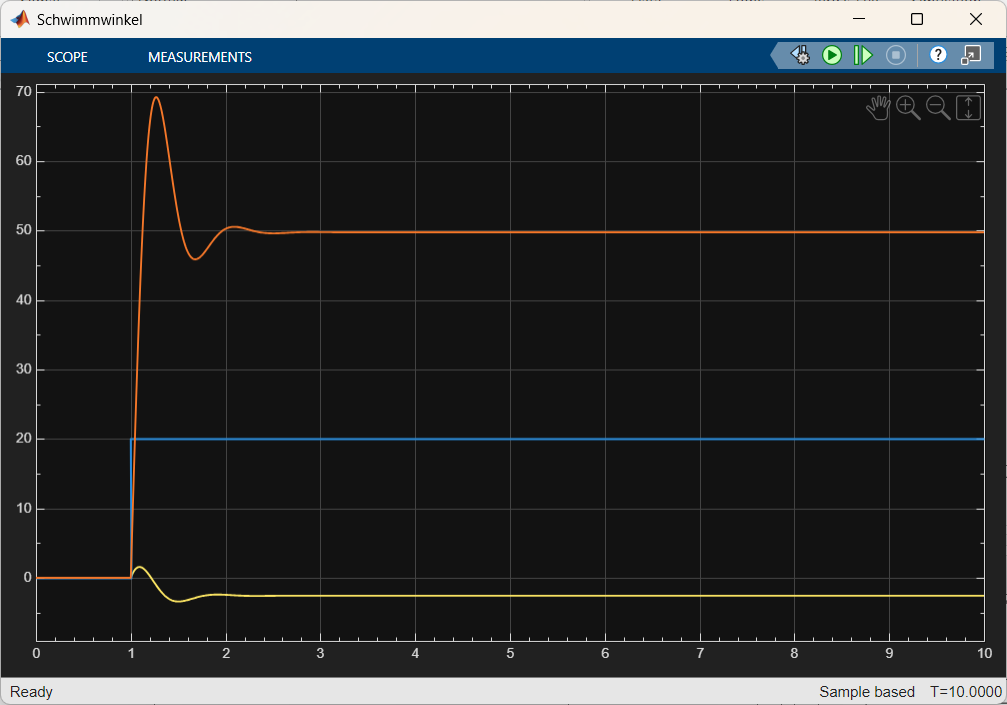

Linearisiert mit delta = 20°

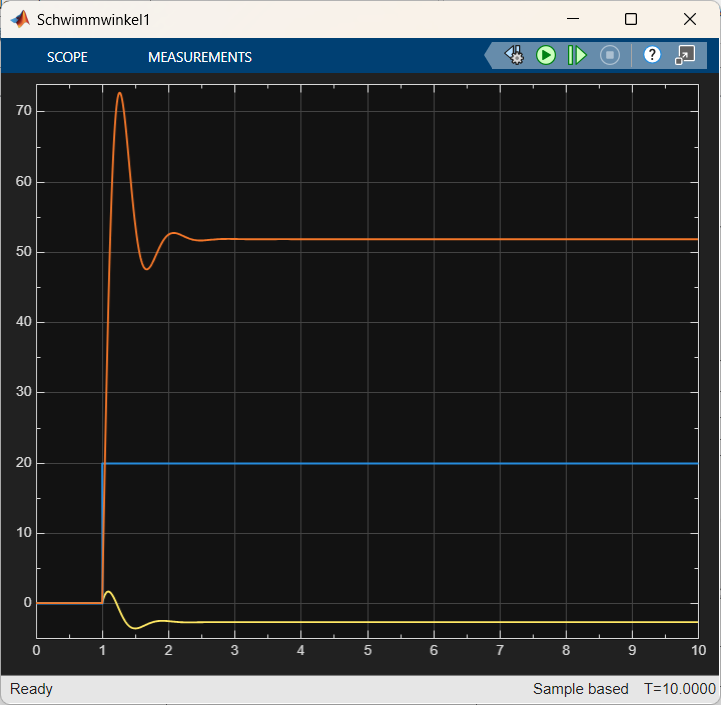

Abweichungen:

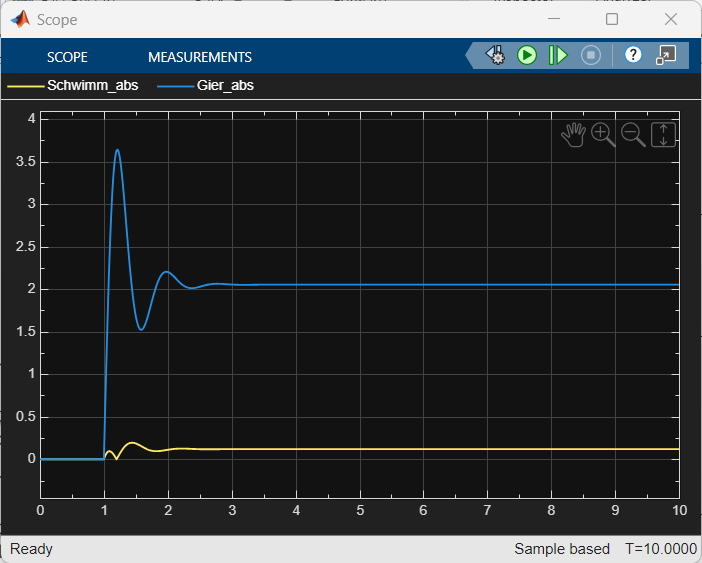

Bei einem Lenkwinkelsprung von 20° zeigt das lineare Modell einen deutlich größeren Ausschlag als das nichtlineare Modell. Die maximale Abweichung zwischen beiden Modellen nimmt erheblich zu.

Dies liegt daran, dass bei größeren Winkeln die vernachlässigten höheren Terme der Taylorentwicklung nicht mehr klein sind. Das lineare Modell ist nur lokal um den Betriebspunkt gültig und kann das nichtlineare Verhalten bei großen Auslenkungen nicht exakt abbilden.

**Berechnung der Abweichung:**

Diese funktioniert für den in Aufgabe2_3.slx eingestellten Radlenkwinkel. Dieser muss dort geändert werden, um die Ergebnisse für ein anderes δ zu erhalten.

% Simulation ausführen und Ergebnis in einer Variable speichern 
out = sim('Aufgabe2_3.slx'); 

% Daten extrahieren
beta_abs = out.simout.Data;
psi_abs = out.simout1.Data;
zeit = out.simout.Time;

% Maximale Abweichungen berechnen für aktuell eingestellten Radlenkwinkel
max_abw_beta = max(beta_abs);
max_abw_psi = max(psi_abs);

% Werte im Live Script anzeigen lassen
fprintf('Die maximale Abweichung im Schwimmwinkel zwischen den Modellen beträgt: %.4f\n', max_abw_beta)

Die maximale Abweichung im Schwimmwinkel zwischen den Modellen beträgt: 0.0031


fprintf('Die maximale Abweichung in der Giergeschwindigkeit zwischen den Modellen beträgt: %.4f\n', max_abw_psi)

Die maximale Abweichung in der Giergeschwindigkeit zwischen den Modellen beträgt: 0.0569


**Interpretation**

Das lineare Modell beschreibt das Fahrzeugverhalten korrekt im Bereich kleiner Lenkwinkel. Mit zunehmender Auslenkung treten jedoch nichtlineare Effekte auf, die im linearen Modell nicht berücksichtigt werden.

Die Abweichung bei δ = 20° zeigt deutlich die Grenzen der Linearisierung. Das lineare Modell ist daher nur für kleine Störungen um den Betriebspunkt geeignet.

#### Aufgabe 4: 

Ermitteln Sie durch Simulation ein Bode-Diagramm für das linearisierte Modell für den Schwimmwinkel bei einer Radlenkwinkelamplitude von δ = 1° für den Frequenzbereich von 0.05Hz bis 100Hz

Interpretieren Sie die Ergebnisse.

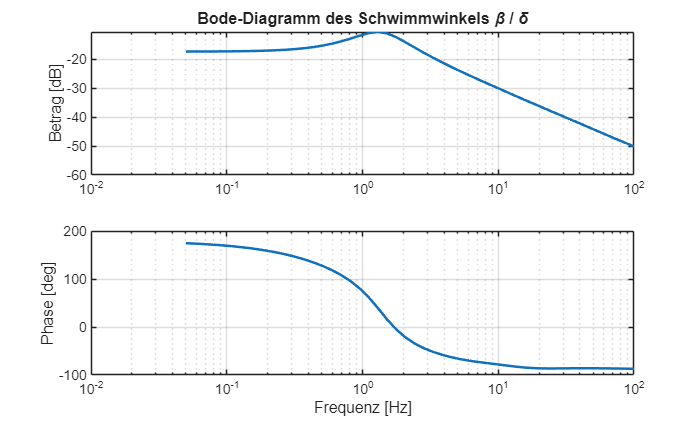

%% Aufgabe 4 – Numerische Bestimmung des Bode-Diagramms

model = "Aufgabe4_bode";
set_param(model, 'SolverType', 'Fixed-step', 'FixedStep', '0.0005');

f = logspace(log10(0.05), log10(100), 50);
omega = 2*pi*f;

%% Speicher
mag = zeros(size(f));
phase = zeros(size(f));

delta_amp = pi/180;   % 1° in rad

for k = 1:length(omega)

    w = omega(k);

    simTime = 10 * (1/f(k));
    simOut = sim(model, 'StopTime', num2str(simTime));

    delta = simOut.simout1;
    beta  = simOut.simout;
    % Sicherstellen, dass Daten vorhanden sind
    if length(beta.Time) < 2
        error('Simulink liefert zu wenig Datenpunkte bei f = %f Hz. Zeitschrittweite prüfen!', f(k));
    end
    t = beta.Time;
    y = beta.Data;
    % Eingang auf gleiche Zeitbasis interpolieren
    u = interp1(delta.Time, delta.Data, t, 'linear', 'extrap');

    % Einschwinganteil abschneiden
    idx = t > t(end)*0.5;
    t_ss = t(idx);
    y_ss = y(idx);
    u_ss = u(idx);


% --- NEUE METHODE: Komplexe Fourier-Projektion ---
    % Multiplikation mit e^(-i*w*t) filtert die exakte Frequenz heraus
    % und ignoriert Rauschen und numerische Ungenauigkeiten völlig.
    u_komplex = mean(u_ss .* exp(-1i * w * t_ss));
    y_komplex = mean(y_ss .* exp(-1i * w * t_ss));
    
    % Komplexe Übertragungsfunktion G(jw)
    G = y_komplex / u_komplex;
    
    % Betrag in dB
    mag(k) = 20*log10(abs(G));
    
    % Phase in Radiant (wird automatisch zwischen -pi und pi ausgegeben)
    phase(k) = angle(G);

end
%% --- UNWRAPPING NACH DER SCHLEIFE ---
% 1. unwrap() repariert Sprünge (funktioniert nur mit Radiant-Vektoren)
phase_unwrapped = unwrap(phase);

% 2. In Grad umrechnen für den Plot
phase_deg = rad2deg(phase_unwrapped);


figure
subplot(2,1,1)
semilogx(f,mag,'LineWidth',1.5)
grid on
ylabel('Betrag [dB]')
title('Bode-Diagramm des Schwimmwinkels \beta / \delta')

subplot(2,1,2)
semilogx(f,phase_deg,'LineWidth',1.5)
grid on
ylabel('Phase [deg]')
xlabel('Frequenz [Hz]')

**Niederfrequenter Bereich**

- Der Betrag ist nahezu konstant.

- Die Phase liegt nahe 0°.

Der Schwimmwinkel folgt dem Lenkwinkel nahezu proportional.

Das Fahrzeug befindet sich im quasi-stationären Kurvenzustand.

**Mittlerer Frequenzbereich**

- Der Betrag beginnt abzufallen.

- Der Phasenverzug nimmt kontinuierlich zu.

Die Fahrzeugträgheit und das Gierträgheitsmoment beeinflussen zunehmend das Verhalten.

Das System reagiert verzögert auf schnellere Lenkanregungen.

**Hochfrequenter Bereich (bis 100 Hz)**

- Deutlicher Abfall des Betrags.

- Phase nähert sich −180°.

Das Fahrzeug kann schnellen Lenkwinkeländerungen nicht mehr folgen.

Das Verhalten entspricht einem gedämpften System 2. Ordnung mit Tiefpasscharakter.

**Zusammenfassung**

Das linearisierte Einspurmodell zeigt ein stabiles, gedämpftes Frequenzverhalten.

Die Quer­dynamik wird maßgeblich durch:

- Fahrzeugmasse

- Gierträgheitsmoment

- Reifensteifigkeiten

- Fahrgeschwindigkeit

bestimmt.

#### Aufgabe 5: 

Bestimmen Sie mit einer Optimierung die Geschwindigkeit, bei der Schwimmwinkel β für einen Radlenkwinkelsprung δ = 5° im eingeschwungen Zustand möglichst klein wird. Verwenden Sie hierzu das linearisierte Modell.

Interpretieren Sie das Fahrverhalten im eingeschwungenen Zustand. Welche besondere Situation ergibt sich?

%% Parameter

m = 2000;       % Masse [kg]
J = 4000;       % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]

delta = deg2rad(5);   % Lenkwinkel [rad]

%% Suchintervall für Geschwindigkeit (m/s)
v_min = 1;     % [m/s]
v_max = 60;    % [m/s] (≈ 216 km/h)

%% Optimierung
obj = @(v) abs(beta_stationary(v,m,J,lv,lh,cv,ch,delta));  % Ziel: |beta_inf|

opts = optimset('TolX',1e-8,'Display','off');
[v_opt, fval] = fminbnd(obj, v_min, v_max, opts);

%% Ergebnisse am Optimum
[beta_inf, psi_dot_inf] = stationary_state(v_opt,m,J,lv,lh,cv,ch,delta);

fprintf('v_opt = %.6f m/s (%.2f km/h)\n', v_opt, 3.6*v_opt);

v_opt = 13.926380 m/s (50.13 km/h)


fprintf('beta_inf = %.6f deg\n', rad2deg(beta_inf));

beta_inf = 0.000000 deg


fprintf('|beta_inf| = %.6f deg\n', rad2deg(abs(beta_inf)));

|beta_inf| = 0.000000 deg


fprintf('psi_dot_inf = %.6f deg/s\n', rad2deg(psi_dot_inf));

psi_dot_inf = 16.693258 deg/s


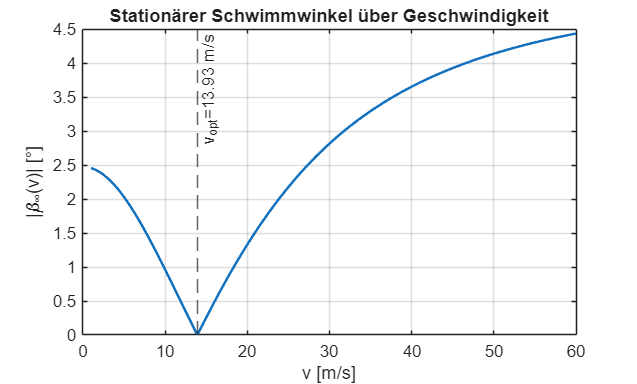


%% Visualisierung
v_plot = linspace(v_min, v_max, 300);
beta_plot = zeros(size(v_plot));
for i = 1:numel(v_plot)
    beta_plot(i) = rad2deg(beta_stationary(v_plot(i),m,J,lv,lh,cv,ch,delta));
end

figure;
plot(v_plot, abs(beta_plot), 'LineWidth', 1.5);
grid on;
xlabel('v [m/s]');
ylabel('|\beta_{\infty}(v)| [°]');
title('Stationärer Schwimmwinkel über Geschwindigkeit');
xline(v_opt, '--', sprintf('v_{opt}=%.2f m/s', v_opt));


%% ===== Funktionen =====

function beta_inf = beta_stationary(v,m,J,lv,lh,cv,ch,delta)
    % gibt den eingeschwungenen Schwimmwinkel (rad) zurück
    [beta_inf, ~] = stationary_state(v,m,J,lv,lh,cv,ch,delta);
end

function [beta_inf, psi_dot_inf] = stationary_state(v,m,J,lv,lh,cv,ch,delta)
    % Stationärer Zustand: x_inf = -A\(B*delta)

    A = [-(cv+ch)/(m*v),           (ch*lh - cv*lv)/(m*v^2) - 1;
          (ch*lh - cv*lv)/J,      -(cv*lv^2 + ch*lh^2)/(J*v)];

    B = [cv/(m*v);
         cv*lv/J];

    x_inf = -A \ (B*delta);      % numerisch stabiler als inv(A)

    beta_inf    = x_inf(1);      % [rad]
    psi_dot_inf = x_inf(2);      % [rad/s]
end

**Beschreibung:**

In Aufgabe 5 wird das linearisierte Einspurmodell verwendet, um die Geschwindigkeit zu bestimmen, bei der der eingeschwungene Schwimmwinkel $\beta$ minimal wird. Im Gegensatz zu Aufgabe 1 wird hier nicht das zeitabhängige Verhalten des nichtlinearen Modells untersucht, sondern ausschließlich der stationäre Zustand des linearen Systems betrachtet.

Zunächst werden die gegebenen Fahrzeugparameter definiert. Dazu gehören die Fahrzeugmasse $m$, das Massenträgheitsmoment um die Hochachse $J$, die Abstände des Schwerpunkts zur Vorder- und Hinterachse $l_v$ und $l_h$ sowie die Schräglaufsteifigkeiten $c_v$ und $c_h$. Der Lenkwinkel $\delta$ wird von Grad in Radiant umgerechnet, da die Berechnungen im Bogenmaß erfolgen.

Das linearisierte Einspurmodell lässt sich in Zustandsraumform darstellen als


$$\dot{x} = A(v),x + B(v),\delta$$


mit dem Zustandsvektor


$$x = \left[\matrix{ \beta \cr \psi_{\dot{}}} \right]$$


Die geschwindigkeitsabhängige Systemmatrix ergibt sich zu


$$A(v) = \left[\matrix{ -\frac{c_v + c_h}{m v} & \frac{c_h l_h - c_v l_v}{m v^2} - 1 \cr \frac{c_h l_h - c_v l_v}{J} & -\frac{c_v l_v^2 + c_h l_h^2}{Jv}} \right]$$


und die Eingangsmatrix lautet


$$B(v) = \left[\matrix{ \frac{c_v}{m v} \cr \frac{c_v l_v}{J}} \right]
$$


Im eingeschwungenen Zustand ist die Zustandsänderung gleich Null, also


$$\dot{x} = 0.$$


Damit folgt


$$0 = A(v)x_\infty + B(v)\delta,$$


und durch Umstellen erhält man den stationären Zustand


$$x_\infty = -A(v)^{-1} B(v)\delta.$$


Der stationäre Schwimmwinkel ergibt sich aus der ersten Komponente dieses Zustandsvektors:


$$\beta_\infty(v) = \left[A(v)^{-1} B(v)\delta\right]_1.$$


Da die Matrix $A(v)$ geschwindigkeitsabhängig ist, hängt auch der stationäre Schwimmwinkel direkt von der Geschwindigkeit $v$ ab. Ziel der Aufgabe ist es, die Geschwindigkeit zu bestimmen, bei der der Betrag des stationären Schwimmwinkels minimal wird. Das Optimierungsproblem lautet daher


$$\min_{v} \left| \beta_\infty(v) \right|.$$


Zur Lösung dieses Problems wird eine Zielfunktion definiert, welche den Betrag des stationären Schwimmwinkels in Abhängigkeit von $v$ berechnet. Die Minimierung erfolgt mithilfe der MATLAB-Funktion `fminbnd`, welche das Minimum einer Funktion in einem vorgegebenen Intervall bestimmt. Als Suchbereich wird ein realistisches Geschwindigkeitsintervall zwischen $v_{\text{min}} = 1 \text{m/s}$ und $v_{\text{max}} = 60 \text{m/s}$ gewählt.

Nach der Optimierung werden die optimale Geschwindigkeit $v_{\text{opt}}$ sowie die zugehörigen stationären Werte für $\beta_\infty$ und $\psi_{\dot{\infty}}$ berechnet und in Grad beziehungsweise Grad pro Sekunde ausgegeben. Zusätzlich wird der Verlauf von $|\beta_\infty(v)|$ über der Geschwindigkeit grafisch dargestellt, um das Minimum visuell zu veranschaulichen.

Die besondere Situation ergibt sich, wenn


$$\beta_\infty(v) = 0$$


In diesem Fall besitzt das Fahrzeug im eingeschwungenen Zustand keinen Schwimmwinkel mehr. Physikalisch bedeutet dies, dass sich das Fahrzeug exakt tangential zur Kurvenbahn bewegt und kein seitliches „Schieben“ auftritt. Dies entspricht einem besonders stabilen Kurvenverhalten im stationären Zustand.